regulatory_regions_file = fopen('wgEncodeRegTfbsClusteredV3.GM12878.merged.bed','rt');
thisline_Reg = fgetl(regulatory_regions_file);

current_chr = '';
x = 0; % number of regulatory regions covered
loading = waitbar(0,'Please wait...');
i = 0

i = 0

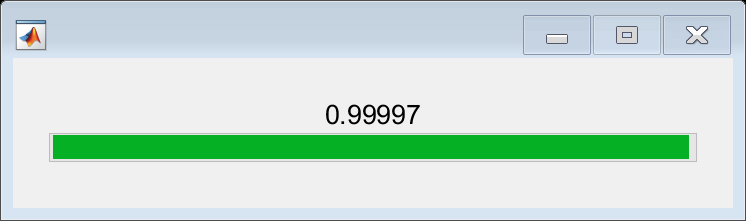

while i < 78794
    r = i/78794;
    waitbar(r,loading,string(r));
    
    if ~ischar(thisline_Reg); break; end  %end of file

    x = x+1;
    C = strsplit(thisline_Reg,"\t");
    chromosome = C(1,1);
    current_chr = string(chromosome{1});

    output_filename = strcat('RegTfbs/', string(chromosome{1}), '_regTfbs.txt');
    output_file = fopen(output_filename, 'wt');
    fprintf(output_file,'%12s\t %12s\t %12s\n','start', 'stop', 'site_id');
    
    while true
        i = i+1;
        start = C(1,2);
        stop = C(1,3);
        start = str2double(start{1});
        stop = str2double(stop{1});
        site_id = C(1,4);
        site_id = site_id{1};
        fprintf(output_file,'%12d\t %12d\t %12s\n',start, stop, site_id);
        
        thisline_Reg = fgetl(regulatory_regions_file);
        if ~ischar(thisline_Reg); break; end  %end of file
        C = strsplit(thisline_Reg,"\t");
        chromosome = C(1,1);
        if current_chr ~= chromosome{1}
            break;
        end
    end
    
    fclose(output_file);
    
end

fclose(regulatory_regions_file);
x

x = 23